# HW #6

Problem 1

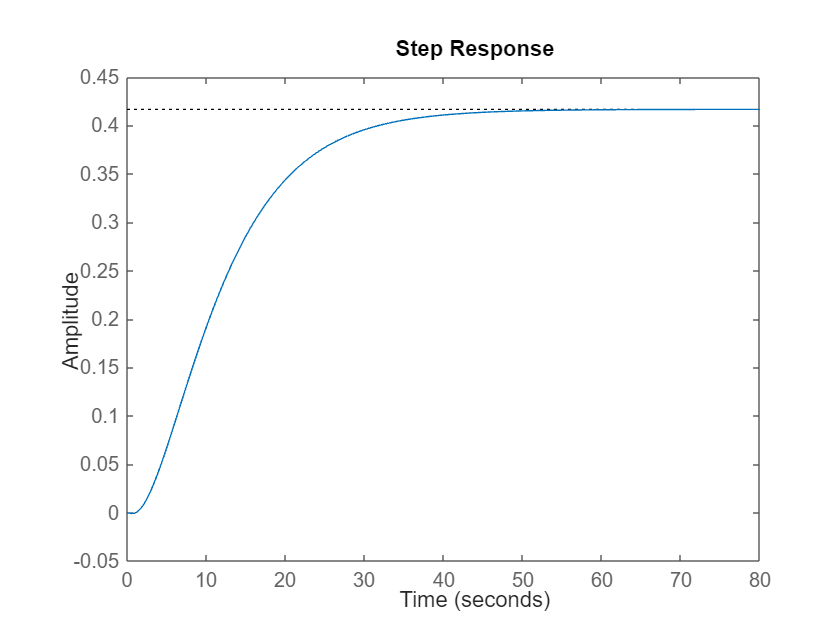

clear
s = tf('s');
Gn = 10/(6*s+1);
Ga = 10*(-0.5*s+1)/(6*s+1)/(0.2*s+1)/(20*s+1);
wa = -10*(4*s^2+20.7*s+1)/((6*s+1)*(0.2*s+1)*(20*s+1));
M = 1/(s+1)^2;
P = [0 0 wa ; -1 M -Gn ; -1 1 -Gn];
[K, CL, GAM] = hinfsyn(P, 1, 1);
N = CL;
step(feedback(Ga*K, 1))

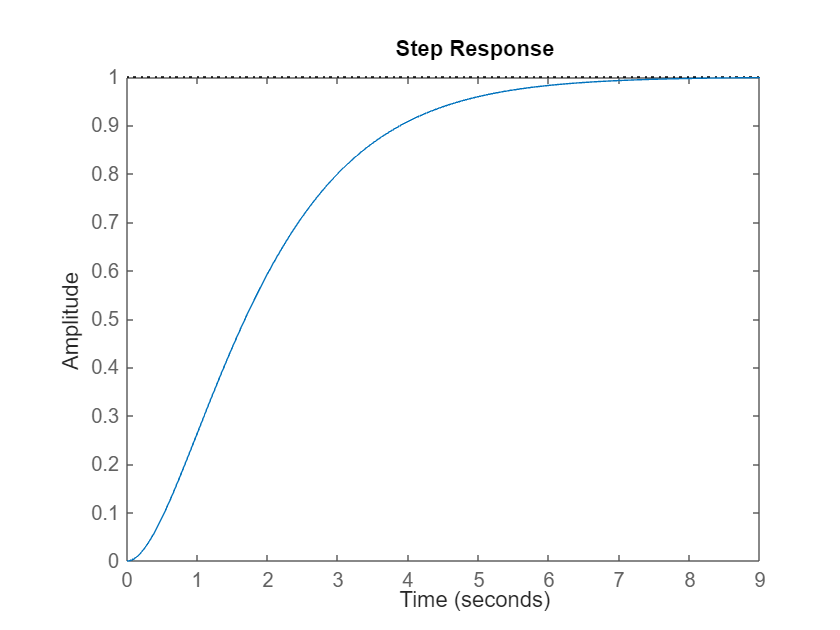

step(M)

norm(N(1,1), 'inf')

ans = 0.4367

Robust stability was achieved.

Problem 2

Part a

clear
HDDModel_DS_Uncertain;
Gv = VCM.NominalValue;
Gp = PZT.NominalValue;
Gv_samples = usample(VCM, 100);
Gp_samples = usample(PZT, 100);
[Pv, infov] = ucover(Gv_samples, Gv, 2);
[Pp, infop] = ucover(Gp_samples, Gp, 2);
wv = infov.W1;
wp = infop.W1;
wv

wv =
 
  A = 
               x1          x2
   x1  -1.925e+05  -1.236e+05
   x2   2.106e+05   1.055e+05
 
  B = 
          u1
   x1   8315
   x2  -8315
 
  C = 
           x1      x2
   y1   231.2  -594.1
 
  D = 
          u1
   y1  9.631
 
Continuous-time state-space model.


wp

wp =
 
  A = 
               x1          x2
   x1       110.1  -4.565e+04
   x2    5.26e+04       -7065
 
  B = 
           u1
   x1   993.7
   x2  -993.7
 
  C = 
          x1     x2
   y1  -1292  -1225
 
  D = 
          u1
   y1  55.09
 
Continuous-time state-space model.


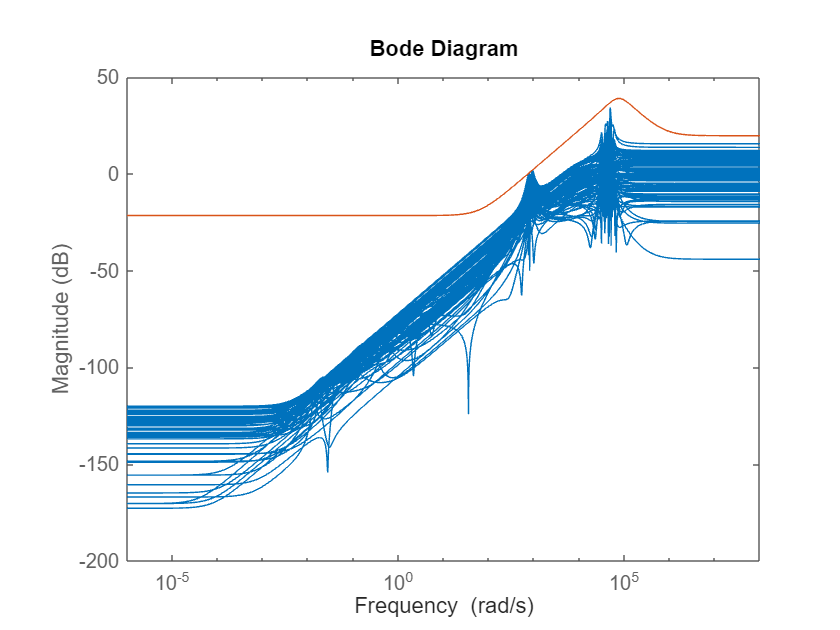

bodemag((Gv_samples - Gv)/Gv, wv)

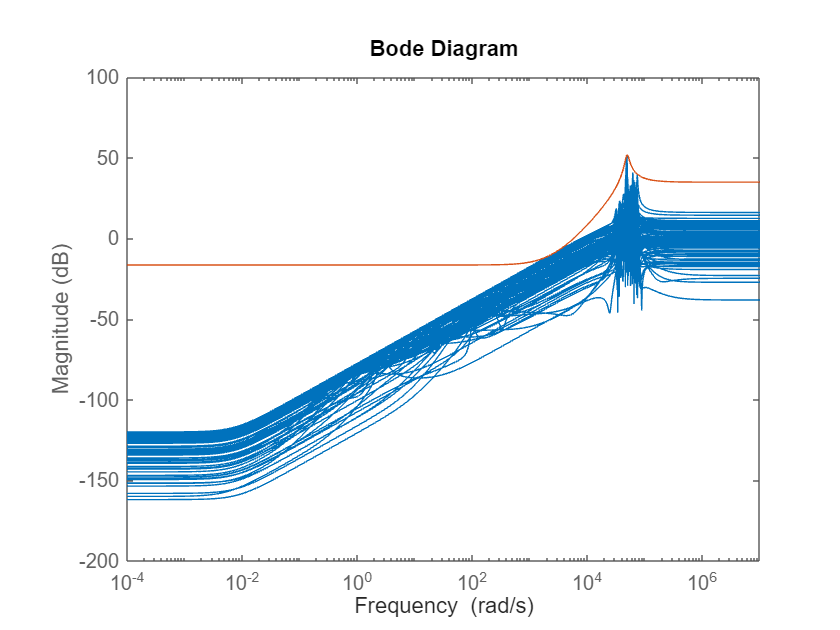

bodemag((Gp_samples - Gp)/Gp, wp)

Part b

wh = 1000;
wl = 0;
w_try = wh;
w_new = 1/2*(wh+wl);
while(abs(w_new-w_try)>.01)
    w_try = w_new;
    Ws = makeweight(1000,w_try,1/2);
    [K, CL, GAM] = mixsyn(Pv, Ws, [], wv);
    S = 1/(1+Gv_samples*K);
    if GAM < 1
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end
GAM

GAM = 1.0000

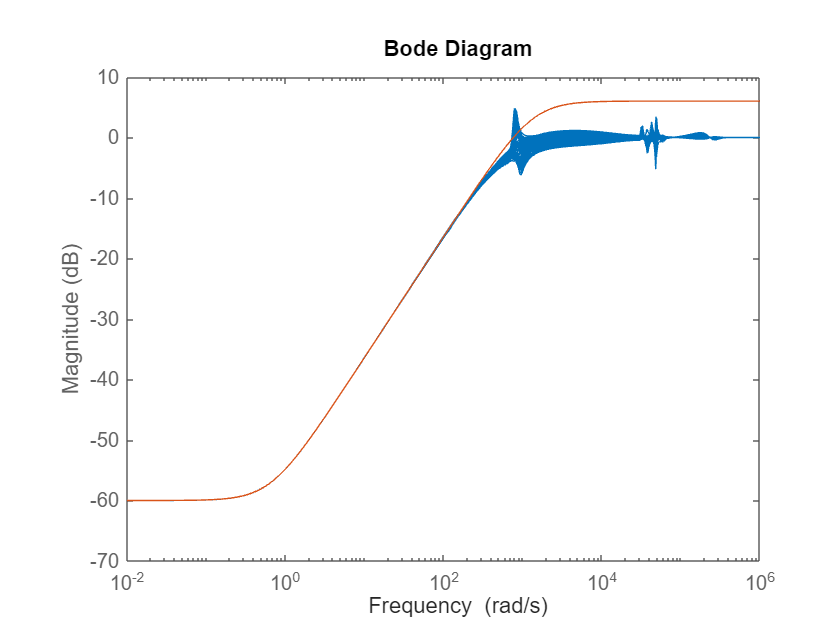

bodemag(S, 1/Ws)

Part c

wh = 1000;
wl = 0;
w_try = wh;
w_new = 1/2*(wh+wl);
gams = [];
while(abs(w_new-w_try)>.01)
    w_try = w_new;
    Ws = makeweight(1000,w_try,1/2);
    P = [0 0 0 wv 0 ; 0 0 0 0 wp ; Ws*Gv Ws*Gp Ws Ws*Gv Ws*Gp ; -Gv -Gp -1 -Gv -Gp];
    [K, CL, GAM] = hinfsyn(P, 1, 2);
    S = 1/(1+[Gv_samples Gp_samples]*K);
    gams = [gams GAM];
    if GAM < 3.5
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end
GAM

GAM = 3.5037

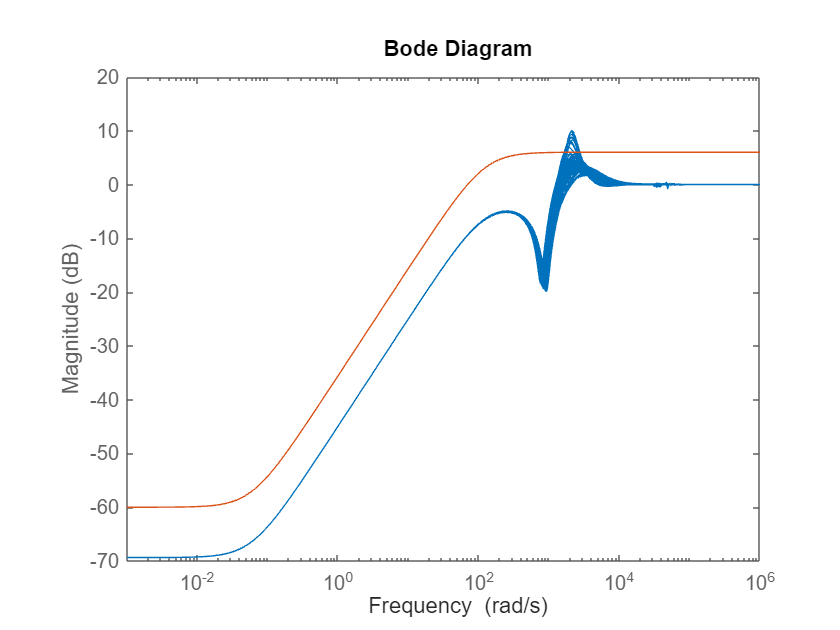

bodemag(S, 1/Ws)

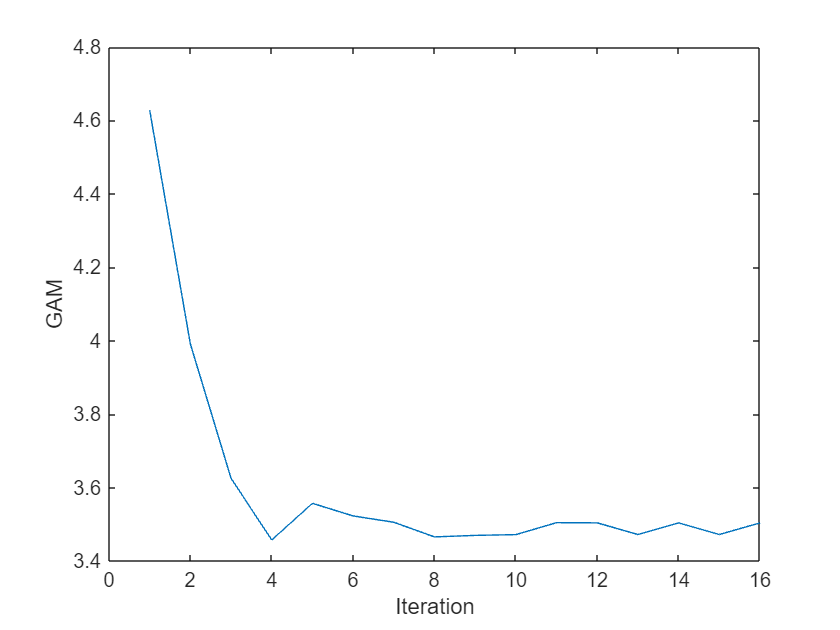

plot(gams)
xlabel("Iteration")
ylabel("GAM")

P_u = [Ws Ws*VCM Ws*PZT ; -1 -VCM -PZT];
N = lft(P_u, K);
[muperf, flag] = perfmu(N)

muperf = 2.3936

flag = 1

Robust performance is not achieved.

Problem 3

Part a

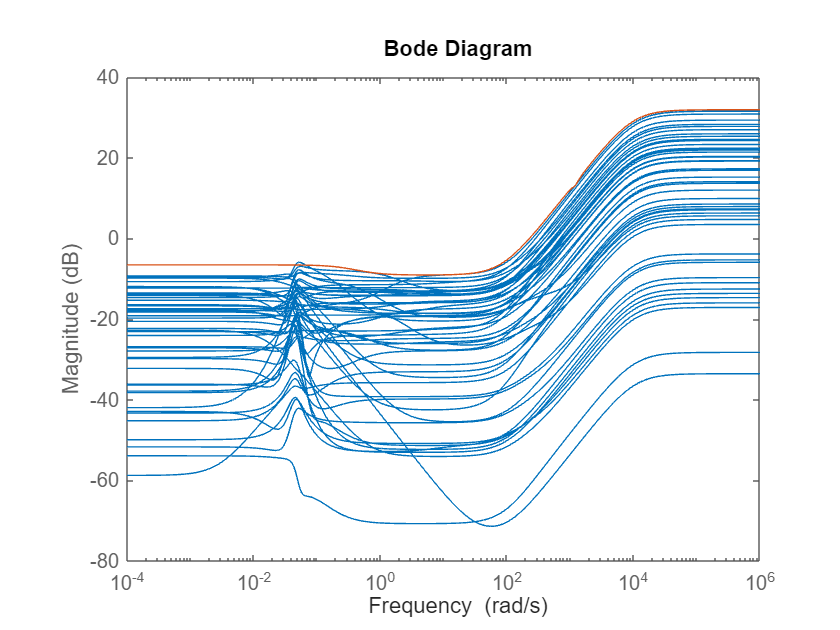

clear
G_samples = load('responses.mat').Gp_samples;
A = [-0.0226 -36.6 -18.9 -32.1 ; 0 -1.9 0.983 0 ; 0.0123 -11.7 -2.63 0 ; 0 0 1 0];
B = [0 0 ; -0.414 0 ; -77.8 22.4 ; 0 0];
C = [0 57.3 0 0 ; 0 0 0 57.3];
D = [0 0 ; 0 0];
G_nom = ss(A, B, C, D);
f = G_samples(:,:,:,1);
[P1, info1] = ucover(f(1,1), G_nom(1,1), 4);
W_del_1 = info1.W1;
bodemag((f(1,1)-G_nom(1,1))/G_nom(1,1), W_del_1)

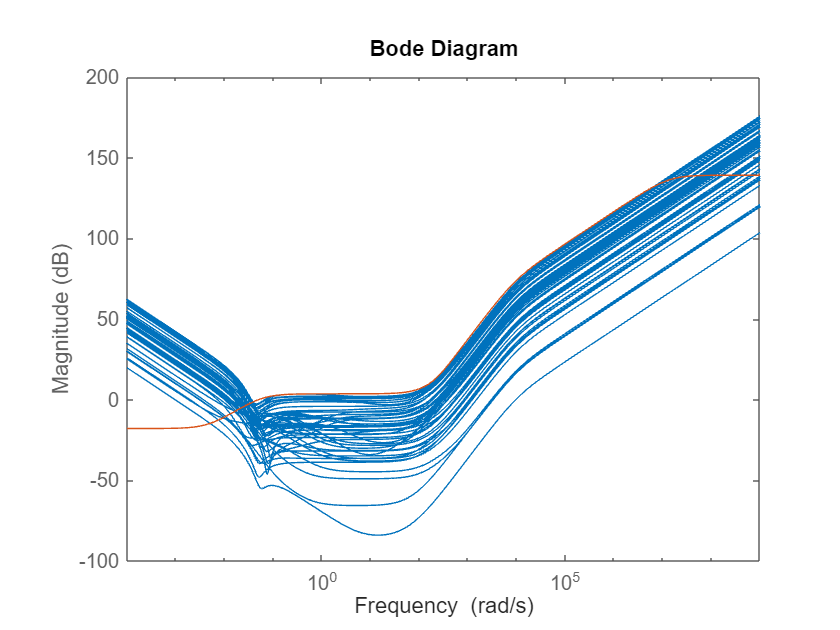

[P2, info2] = ucover(f(1,2), G_nom(1,2), 4);
W_del_2 = info2.W1;
bodemag((f(1,2)-G_nom(1,2))/G_nom(1,2), W_del_2)

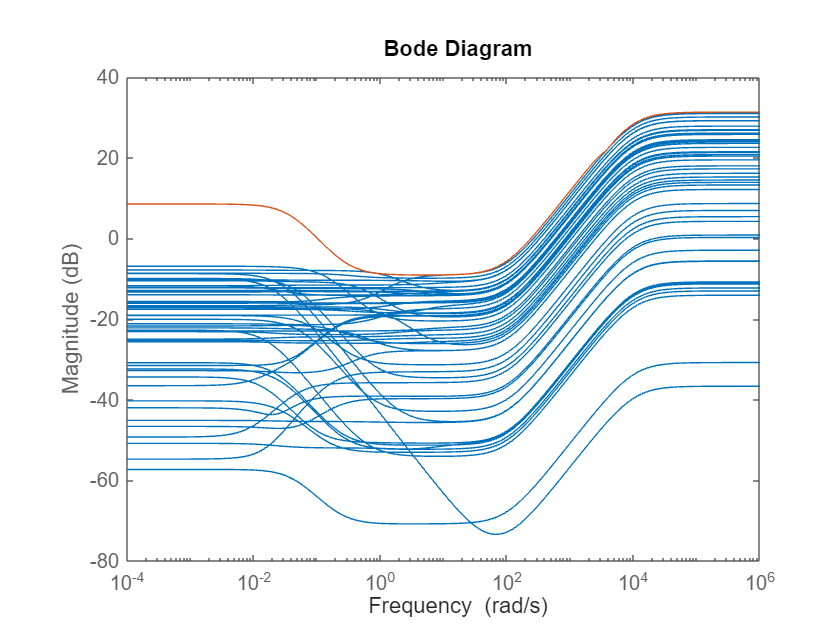

[P3, info3] = ucover(f(2,1), G_nom(2,1), 4);
W_del_3 = info3.W1;
bodemag((f(2,1)-G_nom(2,1))/G_nom(2,1), W_del_3)

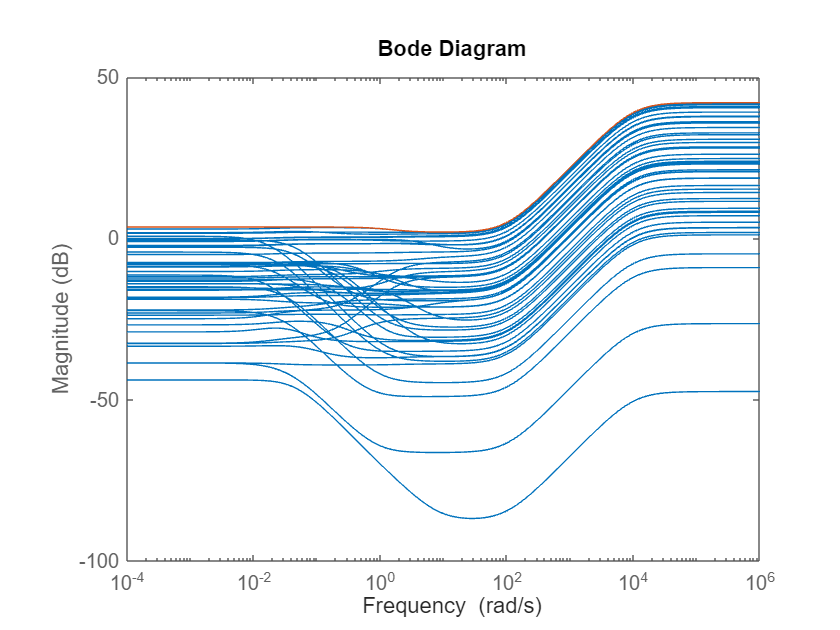

[P4, info4] = ucover(f(2,2), G_nom(2,2), 4);
W_del_4 = info4.W1;
bodemag((f(2,2)-G_nom(2,2))/G_nom(2,2), W_del_4)

Part b

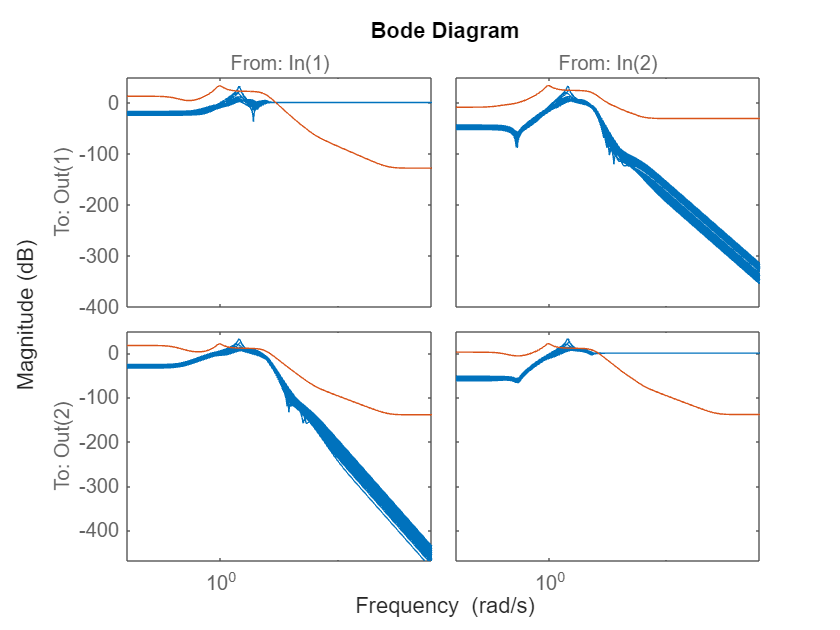

s = tf('s');
W_del = [W_del_1 W_del_2 ; W_del_3 W_del_4];
Wp = [(s+3)/(s+0.03) 0 ; 0 0.5*(s+3)/(s+0.03)];
Wn = [2*(s+1.28)/(s+320) 0 ; 0 2*(s+1.28)/(s+320)];
z = zeros(2);
P = [z z z W_del ; Wp*G_nom z Wp Wp*G_nom ; G_nom Wn ones(2) G_nom];
[K, CL, GAM] = hinfsyn(P, 2, 2);
S = inv(eye(2)+G_samples*K);
bodemag(S, inv(W_del))

d = ultidyn('delta', [2 2]);
G_u = G_nom*(eye(2) + W_del*d);
P_u = [z Wp Wp*G_u ; Wn ones(2) G_u];
N = lft(P_u, K);
[muperf, flag] = perfmu(N)

muperf = 94.0287

flag = 1

This controller is not robustly stable (and thus does not achieve robust performance).